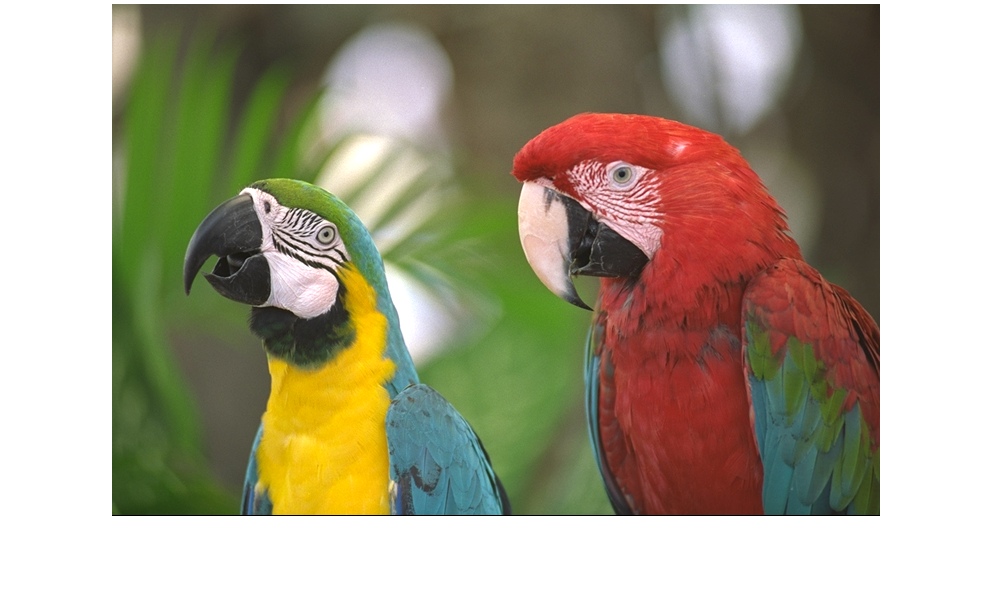

im1=double(imread('image1.png'))/255;

imshow(im1)


im1ycbcr = rgb2ycbcr(im1)

im1ycbcr = im1ycbcr(:,:,1) =

    0.4427    0.4460    0.4561    0.4508    0.4561    0.4561    0.4453    0.4651    0.4554    0.4554    0.4651    0.4587    0.4587    0.4562    0.4562    0.4596    0.4516    0.4461    0.4468    0.4468    0.4461    0.4360    0.4419    0.4273    0.4138    0.4090    0.4056    0.3829    0.3547    0.3404    0.3239    0.3277    0.3322    0.3277    0.3176    0.3239    0.3231    0.3239    0.3239    0.3176    0.3176    0.3142    0.3176    0.3075    0.3176    0.3210    0.3176    0.3184    0.3184    0.3086    0.3184    0.3130    0.3086    0.3183    0.3183    0.3086    0.3049    0.3130    0.3075    0.3142    0.3176    0.3130    0.3086    0.3086    0.3086    0.3086    0.3075    0.3075    0.3130    0.3075    0.3075    0.3041    0.3041    0.3086    0.3130    0.3049    0.3008    0.3075    0.3075    0.3075    0.3075    0.3041    0.3008    0.3075    0.3075    0.3075    0.3075    0.3041    0.3087    0.3087    0.3131    0.3087    0.3131    0.3075    0.3041    0.3075    0.3131

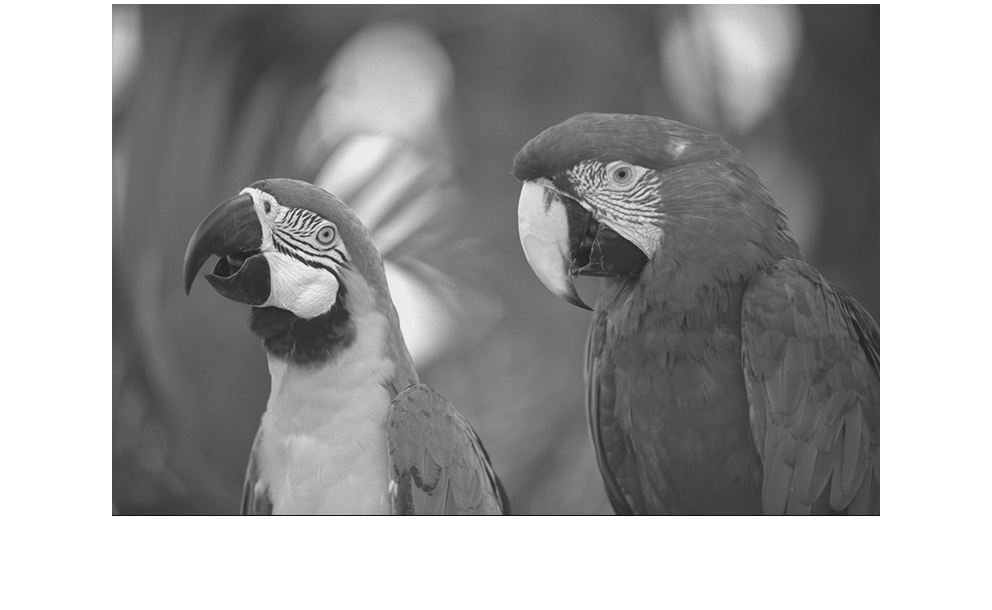

im1y = im1ycbcr(:,:,1);
im1cb = im1ycbcr(:,:,2);
im1cr = im1ycbcr(:,:,3);

imshow(im1y)



im1yd = bdct(im1y, [8 8])

im1yd =     3.9585    4.7586    5.2328    5.7908    6.1370    6.1254    6.0404    5.7797    5.3929    4.8626    4.3584    3.7875    3.3123    3.0134    2.7246    2.8322    2.9972    3.2566    3.6128    4.0045    4.1292    4.1174    4.0909    4.0056    3.8830    3.7377    3.5767    3.4524    3.2908    3.1442    2.9608    2.7770    2.6328    2.5089    2.3997    2.3159    2.2547    2.2269    2.2266    2.2768    2.3594    2.4104    2.5755    2.7332    2.8430    2.9267    2.9179    2.8287    2.7666    2.7505
   -0.2447   -0.1883   -0.1274   -0.1638   -0.0140    0.0070    0.0391    0.0946    0.1458    0.1451    0.1547    0.1651    0.1086    0.0881    0.0215   -0.0310   -0.0644   -0.0859   -0.1171   -0.1003    0.0107    0.0125    0.0162    0.0364    0.0385    0.0406    0.0377    0.0450    0.0457    0.0480    0.0504    0.0480    0.0379    0.0301    0.0380    0.0245    0.0124    0.0135   -0.0073   -0.0208   -0.0168   -0.0222   -0.0581   -0.0315   -0.0253   -0.0245    0.0355    0.0153    0.0199 




% imshow(ibdct(im1yr, [8 8], size(im1y)))

% Q1=0.1;
% im1ydq = bquant(im1yd, Q1);
% im1ydr = brec(im1ydq, Q1);
% im1yr = ibdct(im1ydr, [8 8], size(im1y));
% figure, imshow(im1yr - im1y);

QL=repmat(1:8, 8, 1); QL=(QL+QL'-9)/8

QL =    -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0
   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250
   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500
   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750
   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000
   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250
   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500
         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750


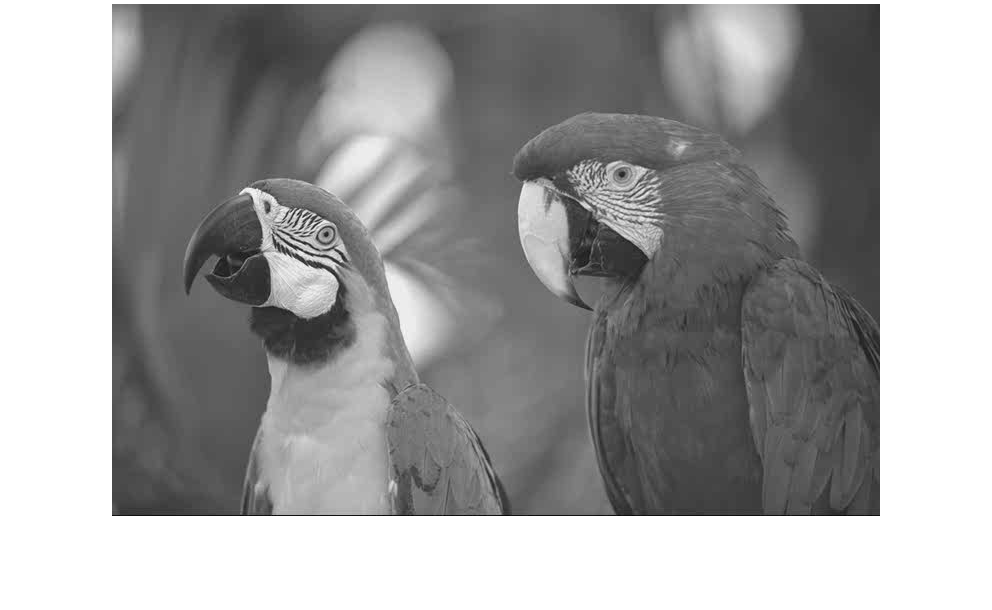

k1=0.1; k2=0.3;
Q2=k1*(1+k2*QL);
im1ydq = bquant(im1yd, Q2);
im1ydr = brec(im1ydq, Q2);
im1yr = ibdct(im1ydr, [8 8], size(im1y));
figure, imshow(im1yr);


dist = mean((im1y(:)-im1yr(:)).^2)

dist = 1.3117e-04

psnr = 10*log10(1/dist)

psnr = 38.8217



% Source coding

p = ihist(im1ydq(:))

p =            1           0           1           0           1           2           2           4           2           8           7           9          11           8          34          35          51          72         105         180         313         589        1403        6576      367737        6928        1439         677         328         211          97          81          40          40          21          20          11           7           4           4           4           3           5           3           3          13          28          41          31          59



% Static huffman
% bits = huffman(p)
% bpp = bits/(length(im1y(:,1)) * length(im1y(1,:)))
pixels = length(im1y(:,1)) * length(im1y(1,:))

pixels = 393216

% Dynamic huffman
bits=0;
for k=1: size (im1ydq, 1)
    p = ihist(im1ydq(k,:));
    bits = bits + huffman(p);
end
bpp = bits/pixels

bpp = 1.1845


bits = sum(jpgrate(im1ydq, [8 8]));
bpp = bits/pixels

bpp = 0.3468

Code


% [psnr, bpp] = transcoder('image1.png', [40 40], 0.1, 0.1)

% psnr
% bpp

numberOfBlockSizes = 5;
blockSizeStart = 2;

numberOfStepSizes = 15

numberOfStepSizes = 15

stepSizeScale = 0.3

stepSizeScale = 0.3000

stepSizeStart = 0.1

stepSizeStart = 0.1000


res = zeros(2, numberOfStepSizes, numberOfBlockSizes);
size(res)

ans =      2    15     5


stepsize_lower = 0.01

stepsize_lower = 0.0100

stepsize_upper = 0.5

stepsize_upper = 0.5000

stepsizes = logspace(log10(stepsize_lower),log10(stepsize_upper),numberOfStepSizes);


for blockSize = 1:numberOfBlockSizes
    blockSizeStart^blockSize
    for stepSize = 1:numberOfStepSizes
        [psnr, bpp] = transcoder( ...
            'image1.png', ...
            [blockSizeStart^blockSize blockSizeStart^blockSize], ...
            stepsizes(stepSize), ...
            stepsizes(stepSize)*1.2, ...
            0.5, ...
            true, ...
            "bdct", ...
            "uniform" ...
        );

            %             stepSize*stepSizeScale + stepSizeStart, ...
%             stepSize*stepSizeScale + stepSizeStart, ...
        res(:, stepSize, blockSize) = [psnr, bpp];
    end
end

ans = 2

ans = 4

ans = 8

ans = 16

ans = 32


res

res = res(:,:,1) =

   43.2233   42.0442   40.6998   39.1909   37.6031   35.7661   33.9603   32.1077   29.9877   27.9528   25.4607   23.2206   20.9511   20.0185   15.0672
    3.1484    2.7421    2.2469    1.8642    1.5818    1.3717    1.2153    1.0996    1.0097    0.9440    0.8948    0.8584    0.8310    0.8049    0.7947


res(:,:,2) =

   43.4356   42.4066   41.2614   40.0413   38.7701   37.4170   35.9649   34.4005   32.8994   31.2576   29.2706   27.9172   25.6157   23.4214   21.6449
    2.7780    2.2556    1.8001    1.3829    1.0742    0.9070    0.7279    0.5905    0.4837    0.4028    0.3428    0.2978    0.2654    0.2429    0.2245


res(:,:,3) =

   43.4989   42.5118   41.4420   40.3322   39.1882   37.9472   36.6834   35.3698   34.0071   32.6111   31.2178   29.8102   28.4266   26.9326   25.3299
    2.6580    2.1579    1.6974    1.3084    1.0123    0.7926    0.6296    0.4988    0.3972    0.3165    0.2518    0.1997    0.1625    0.1336    0.1135


res(:,:,4) =

   43.4806   42.5145   41.

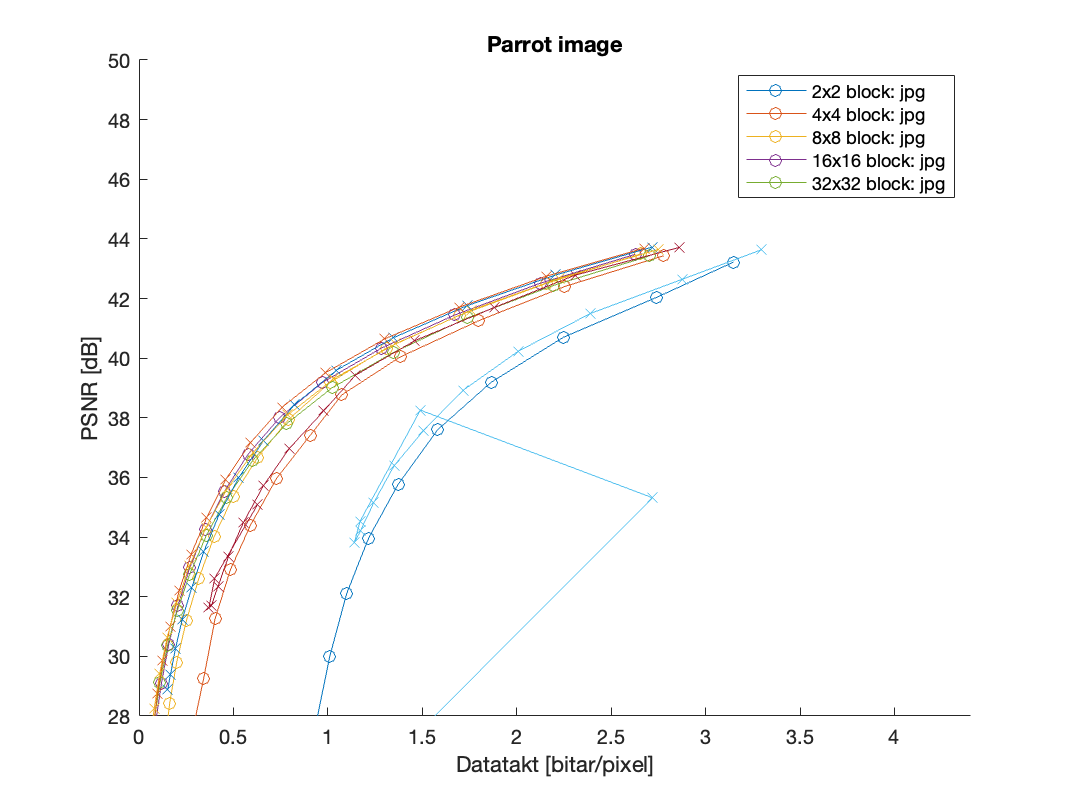

figure
% xlim([0, 1.4])
% ylim([28, 46])

xlim([0, 4.4])
ylim([28, 50])

hold on
for i = 1:numberOfBlockSizes
    plot(res(2,:,i), res(1,:,i),'-o')
end

for i = 1:numberOfBlockSizes
    plot(huffmanRes(2,:,i), huffmanRes(1,:,i),'-x')
end
title('Parrot image')
legend('2x2 block: jpg', '4x4 block: jpg', '8x8 block: jpg', ...
       '16x16 block: jpg', '32x32 block: jpg')
ylabel('PSNR [dB]')
xlabel('Datatakt [bitar/pixel]')
hold off

huffmanRes = res

huffmanRes = huffmanRes(:,:,1) =

   43.6346   42.6459   41.5007   40.2317   38.9242   37.5838   36.3909   35.1647   34.2054   33.8101   34.5366   38.2580   35.3180   23.9097   16.6042
    3.2951    2.8763    2.3907    2.0076    1.7162    1.5081    1.3504    1.2439    1.1722    1.1403    1.1706    1.4898    2.7190    0.9224    0.7958


huffmanRes(:,:,2) =

   43.7197   42.7847   41.7008   40.5881   39.4244   38.2305   36.9704   35.7169   34.4902   33.3501   32.3516   31.6938   31.6232   32.6263   35.0909
    2.8637    2.3095    1.8812    1.4603    1.1453    0.9781    0.7955    0.6583    0.5528    0.4738    0.4187    0.3829    0.3699    0.4011    0.6280


huffmanRes(:,:,3) =

   43.7252   42.7919   41.7672   40.6843   39.5931   38.4374   37.2253   35.9922   34.7494   33.5123   32.3109   31.2341   30.2478   29.4016   28.8796
    2.7168    2.2065    1.7395    1.3457    1.0447    0.8237    0.6583    0.5278    0.4236    0.3432    0.2796    0.2286    0.1926    0.1670    0.1518


huffmanRes(: